# **Preprocess Data**

**Author:** Alexander Dunn

**Date:** 03/22/23

**Description: **Tide, temperature and humidity data are stored in several text files within an SD card on each device. This script compiles all of these separate files into one text file while filtering out bad data points and sorting the data properly. This script also allows for external temperature data to be incorporated.

## Process Data

Click the run button to begin.

clear

folder = string(inputdlg("Filepath to the folder containing the 'Data' folder:")) % Path to folder containing Data folder

folder = "/Users/alexanderdunn/Desktop/Work/Work Files/Testing/P5A Roof 3"

stationList = {'Morro Bay T Pier', 'Cayucos Pier', 'Cal Poly Pier', ...
               'San Simeon Pier', 'Indoor Lab', 'Outdoor Lab', 'Other'};
stationIDs = ["MB01", "CA01", "CP01", "SS01", "LA01", "LA02", "NA00"];

station = listdlg('PromptString', "Station Name:", ...
                 'ListString', stationList, ...
                 'SelectionMode', 'single', ...
                 'ListSize', [200 75]);

stationID = stationIDs(station)

stationID = "LA02"


if station == length(stationList)
    stationName = string(inputdlg("Station Name:"))
else
    stationName = string(stationList(station))
end

stationName = "Outdoor Lab"

gaugeID = string(inputdlg("Gauge ID:"))

gaugeID = "P5A"


try
    filepath = append(folder, "/logFile.txt");
    
    logData = importdata(filepath);
    coordinates = string(logData.data(2)) + "°, " + string(logData.data(3)) + "°, " + string(logData.data(4)) + " meters above MSL";
catch
    coordinates = string(inputdlg("Gauge Coordinates:"));
end
coordinates

coordinates = "35.3013°, -120.665°, 100.9 meters above MSL"


times = nan(1, 10000000)';
dists = nan(1, 10000000)';
temps = nan(1, 10000000)';
hums = nan(1, 10000000)';
solar = nan(1, 10000000)';
battery = nan(1, 10000000)';

filepath = append(folder, "/Data/*.txt");

try 
    files = dir(filepath);
    names = files.name;
catch
    disp("Gauge files not found")
    return
end

string = sprintf("Processing %d gauge data files, this may take a moment...", length(files));
disp(string)

Processing 89 gauge data files, this may take a moment...



index = 1;
errors = 0;
for file = 1:length(files)
    filepath = append(folder, "/Data/", files(file).name);
    headerlinesIn = 1;
    delimiterIn = ',';

    data = importdata(filepath,delimiterIn,headerlinesIn);

    try
        times(index:index+length(data.data)-1) = data.data(:,1);
        dists(index:index+length(data.data)-1) = data.data(:,2);
        temps(index:index+length(data.data)-1) = data.data(:,3);
        hums(index:index+length(data.data)-1) = data.data(:,4);
        
        try
            battery(index:index+length(data.data)-1) = data.data(:,5);
            solar(index:index+length(data.data)-1) = data.data(:,6);
        catch ME
            % No voltage data
        end
        
        index = index + length(data.data);
    catch ME
        % Some error occurs, do nothing and move on
        errors = errors + 1;
    end
end

total = length(files);
percent = 100*errors/total;
fprintf("%d errors out of %d files, %0.2f percent.", errors, total, percent)

0 errors out of 89 files, 0.00 percent.

%-------------------------------------
% Clean up data
%-------------------------------------

disp("Processing gauge data")

Processing gauge data


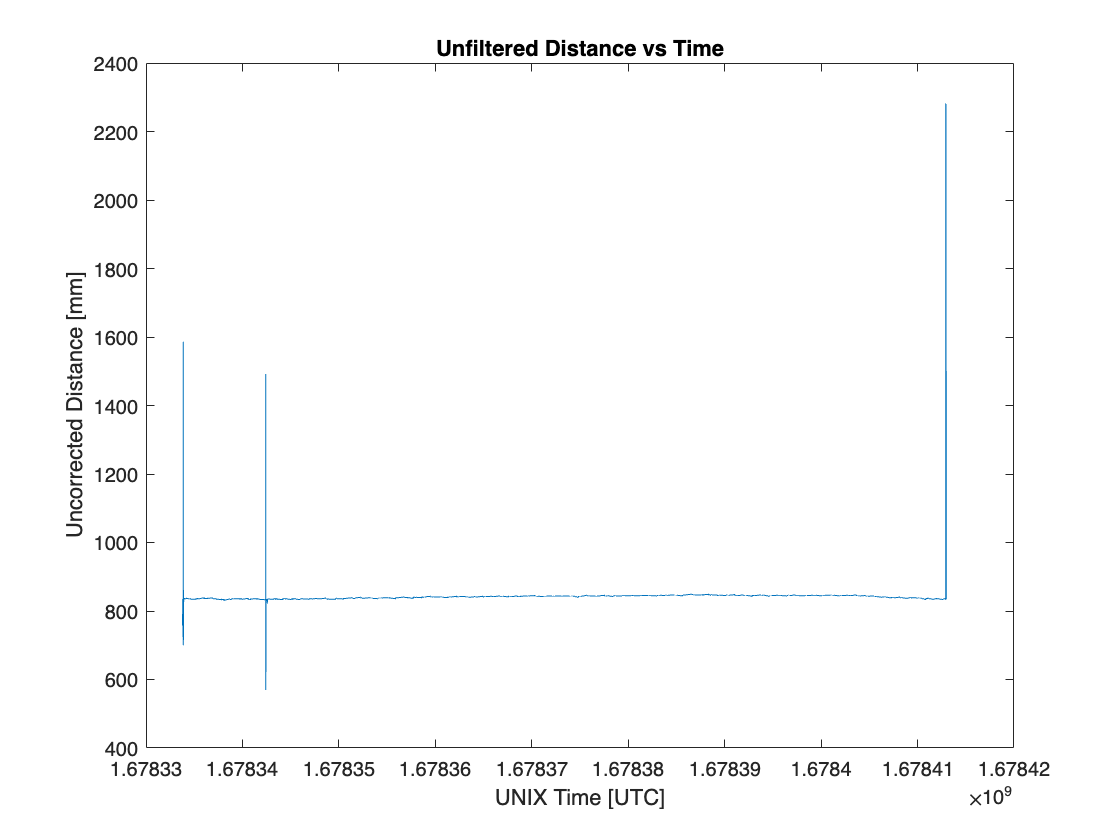


totalMeasurements = length(find(times(times > 0)));
times(times <= 1641024000) = NaN; % Currently set to remove all timestamps before 2022
times(times >= posixtime(datetime(datestr(now), "TimeZone", "GMT"))+86400) = NaN; % Currently set to remove all timestamps after the current date

figure()
plot(times, dists);
xlabel("UNIX Time [UTC]")
ylabel("Uncorrected Distance [mm]")
title("Unfiltered Distance vs Time")


totalData = length(find(times(times > 0)));
lowBad = length(find(dists(dists <= 500)));
highBad = length(find(dists(dists >= 9999)));
fprintf("%d measurements were 500 or less. %0.2f%%.", lowBad, 100*lowBad/totalMeasurements)

0 measurements were 500 or less. 0.00%.

fprintf("%d measurements were 9999 or more. %0.2f%%.", highBad, 100*highBad/totalMeasurements)

0 measurements were 9999 or more. 0.00%.

newDists = dists;
newDists(newDists <= 500) = NaN;
newDists(newDists >= 9999) = NaN;

[newTimes, key] = sort(times, 'ascend');
newDists = newDists(key);
hums = hums(key);
temps = temps(key);
solar = solar(key);
battery = battery(key);

[newTimes, key] = uniquetol(newTimes, 'byrows', true);
newDists = newDists(key);
hums = hums(key);
temps = temps(key);
solar = solar(key);
battery = battery(key);

goodIndeces = find(~isnan(newDists));
newTimes = newTimes(goodIndeces);
newDists = newDists(goodIndeces);
hums = hums(goodIndeces);
temps = temps(goodIndeces);
solar = solar(goodIndeces);
battery = battery(goodIndeces);

goodIndeces = find(not(isnan(newTimes)));
totalTimes = newTimes(goodIndeces);
totalDists = newDists(goodIndeces);
totalTemps = temps(goodIndeces);
totalHums = hums(goodIndeces);
solar = solar(goodIndeces);
battery = battery(goodIndeces);

startTime = datetime(totalTimes(1), 'ConvertFrom', 'posixtime')

startTime = datetime
   09-Mar-2023 03:49:52


endTime = datetime(totalTimes(end), 'ConvertFrom', 'posixtime')

endTime = datetime
   10-Mar-2023 01:49:28


Seconds = range(totalTimes)';
Hours = Seconds./(60^2);
Days = Hours./24;
Weeks = Days./7;
Months = Weeks./4;
testLength = table(Hours, Days, Weeks, Months)

testLength = 1×4 table
    Hours      Days       Weeks      Months 
    ______    _______    _______    ________

    21.993    0.91639    0.13091    0.032728



dates = datetime(totalTimes, 'ConvertFrom', 'posixtime');
% dates = datetime(dates, 'TimeZone', 'UTC');
% dates.TimeZone = 'local';
dates = dates - hours(8);


% sampleStart = "27-Jan-2023 18:00:00";
% 
% dates(dates < sampleStart) = NaT;


timeDiffs = diff(dates);
timeDiffs2 = timeDiffs;
timeDiffs2(timeDiffs < minutes(1)) = NaN;

% Estimate Duty Cycle
switchIdx = find(timeDiffs > seconds(30));
interval = round(median(diff(dates(switchIdx))), 'minutes');

sleep = round(median(timeDiffs2, 'omitnan'), 'minutes');
on = interval - sleep;

duty = sprintf("Duty Cycle: %d minutes on, %d minutes off, centered on %d minute intervals.", ...
               minutes(on), minutes(sleep), minutes(interval));
disp(duty)

Duty Cycle: 5 minutes on, 10 minutes off, centered on 15 minute intervals.


% Format timeID
timeID = sprintf("%d-%02d-%02d", startTime.Year, startTime.Month, startTime.Day);

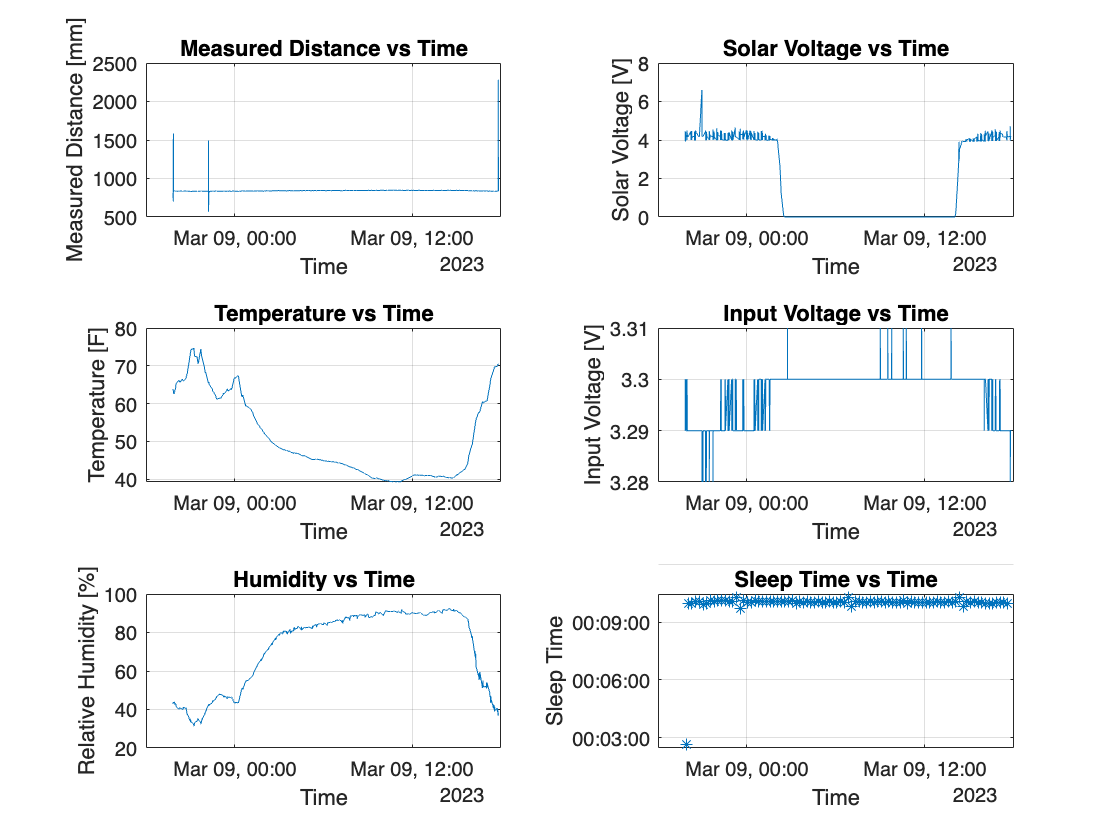

%-------------------------------------
% Plot initial data
%-------------------------------------

figure();
tiledlayout(3,2);

nexttile;
plot(dates, totalDists)
grid on
title("Measured Distance vs Time")
xlabel("Time");
ylabel("Measured Distance [mm]")

nexttile;
plot(dates, solar)
grid on
title("Solar Voltage vs Time")
xlabel("Time");
ylabel("Solar Voltage [V]")

nexttile;
plot(dates, totalTemps)
grid on
title("Temperature vs Time")
xlabel("Time");
ylabel("Temperature [F]")

nexttile;
plot(dates, battery)
grid on
title("Input Voltage vs Time")
xlabel("Time");
ylabel("Input Voltage [V]")

nexttile;
plot(dates, totalHums)
grid on
title("Humidity vs Time")
xlabel("Time");
ylabel("Relative Humidity [%]")

nexttile;
plot(dates(1:end-1), timeDiffs2, "*")
grid on
title("Sleep Time vs Time")
xlabel("Time");
ylabel("Sleep Time")

%-------------------------------------
% Ask about external temperature gauge
%-------------------------------------

list = {'Yes', 'No'};

tCheck = listdlg('PromptString', "Include external temperature data?", ...
                 'ListString', list, ...
                 'SelectionMode', 'single', ...
                 'ListSize', [200 75]);

% If they said yes to external temperature
if tCheck == 1
    tfolder = inputdlg("Enter filepath to folder containing temperature sensor 'Data' folder:");
    disp("Processing temperature data files...")

    tfilepath = append(tfolder, "/Data/*.txt");
    try 
        tfiles = dir(tfilepath);
        names = tfiles.name;
    catch
        disp("Temperature files not found")
        tCheck = 2;
    end

    tTimes = nan(1, 10000000)';
    tTemps = nan(1, 10000000)';
    tHums = nan(1, 10000000)';
    
    index = 1;
    errors = 0;
    
    for file = 1:length(tfiles)
        tfilepath = append(tfolder, "/Data/", tfiles(file).name);
        headerlinesIn = 1;
        delimiterIn = ',';
    
        data = importdata(tfilepath,delimiterIn,headerlinesIn);
        try
            tTimes(index:index+length(data.data)-1) = data.data(:,1);
            tTemps(index:index+length(data.data)-1) = data.data(:,2);
            tHums(index:index+length(data.data)-1) = data.data(:,3);
            
            index = index + length(data.data);
        catch ME
            % Some error occurs, do nothing and move on
            errors = errors + 1;
        end
    end
    
    total = length(tfiles);
    percent = 100*errors/total;
    fprintf("%d errors out of %d files, %0.2f percent.", errors, total, percent)
end

%-------------------------------------
% Clean up temperature data
%-------------------------------------

if tCheck == 1

    disp("Processing external temperature data")

    totaltMeasurements = length(find(tTimes(tTimes > 0)));
    tTimes(tTimes <= 1577865600) = NaN; % Currently set to remove all timestamps before 2020
    times(times >= posixtime(datetime(datestr(now), "TimeZone", "GMT"))+86400) = NaN; % Currently set to remove all timestamps before 2020
    tTemps(tTemps == 0) = NaN;
    tHums(tHums == 0) = NaN;

    [newtTimes, tkey] = sort(tTimes, 'ascend');
    tHums = tHums(tkey);
    tTemps = tTemps(tkey);

    goodtIndeces = find(not(isnan(newtTimes)));
    totaltTimes = newtTimes(goodtIndeces);
    totaltTemps = tTemps(goodtIndeces);
    totaltHums = tHums(goodtIndeces);
    
    totaltData = length(totaltTimes);

    starttTime = datetime(totaltTimes(1), 'ConvertFrom', 'posixtime')
    endtTime = datetime(totaltTimes(end), 'ConvertFrom', 'posixtime')
    tSeconds = range(totaltTimes)';
    tHours = tSeconds./(60^2);
    tDays = tHours./24;
    tWeeks = tDays./7;
    tMonths = tWeeks./4;
    testtLength = table(tHours, tDays, tWeeks, tMonths)

    tDates = datetime(totaltTimes, 'ConvertFrom', 'posixtime');
    tDates = tDates - hours(8);

    figure();
    tiledlayout(1,2);

    nexttile;
    plot(tDates, totaltTemps)
    grid on
    title("External Temperature vs Time")
    xlabel("Time");
    ylabel("Temperature [F]")
    
    nexttile;
    plot(tDates, totaltHums)
    grid on
    title("External Humidity vs Time")
    xlabel("Time");
    ylabel("Relative Humidity [%]")
end

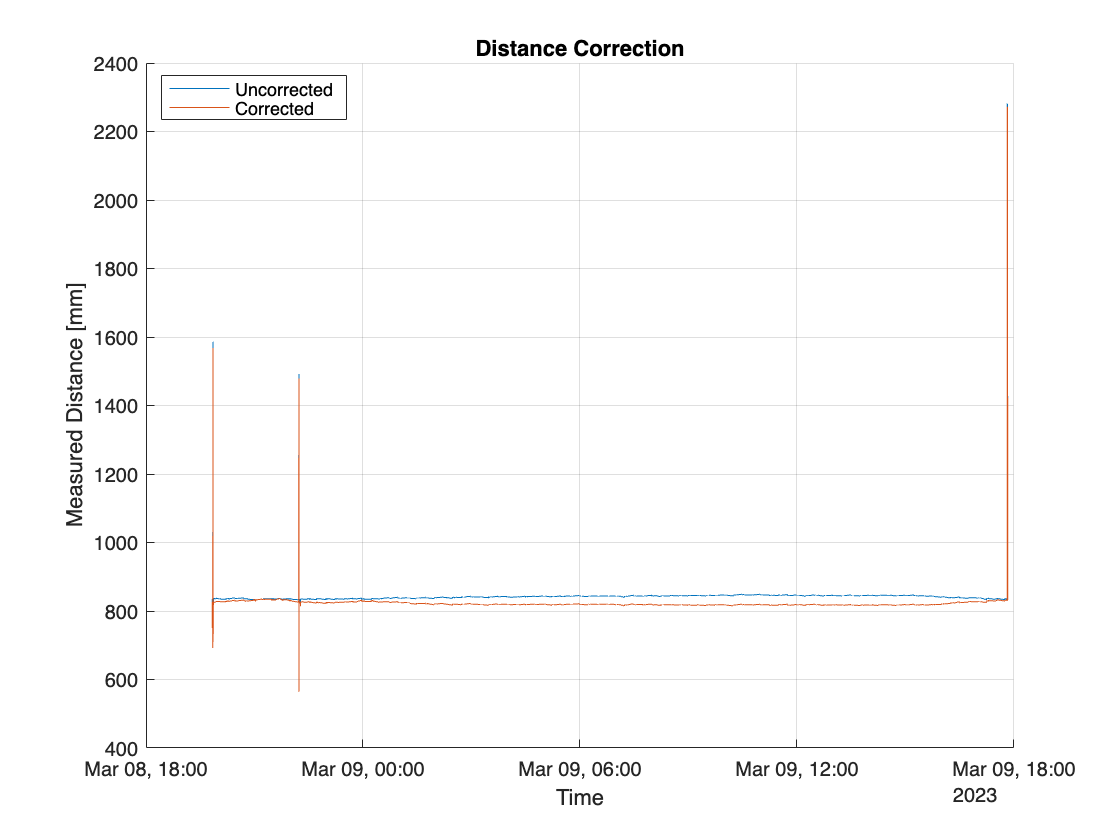

%-------------------------------------
% Correct distance measurements
%-------------------------------------

if tCheck == 1
    interpTemps = interp1(totaltTimes, totaltTemps, totalTimes);
    interpHums = interp1(totaltTimes, totaltHums, totalTimes);

    correctedDistances = round(correctedDists(totalDists, interpTemps, interpHums));

    figure()
    hold on
    plot(totalTimes, totalDists)
    plot(totalTimes, correctedDistances)
    grid on
    title("Distance Correction")
    xlabel("Time");
    ylabel("Measured Distance [mm]")
    legend("Uncorrected", "Corrected", 'location', 'best')
else
    correctedDistances = round(correctedDists(totalDists, totalTemps, totalHums));

    figure()
    hold on
    plot(dates, totalDists)
    plot(dates, correctedDistances)
    grid on
    title("Distance Correction")
    xlabel("Time");
    ylabel("Measured Distance [mm]")
    legend("Uncorrected", "Corrected", 'location', 'best')
end

%-------------------------------------
% Create text file(s)
%-------------------------------------

disp("Writing text files")

Writing text files



mkdir(folder + "/Data Products");

fileName = folder + "/Data Products/" + stationID + "_" + timeID + "_allData.txt";

fid = fopen(fileName, "W");
fprintf(fid, "Station: %s (%s) - Location: %s\n", stationName, stationID, coordinates);
fprintf(fid, "Gauge ID: %s\n", gaugeID);
fprintf(fid, "%s\n", duty);
fprintf(fid, "Time Units: Seconds since 01-Jan-1970 00:00:00 GMT\n");
fprintf(fid, "Start Date: %s GMT\n", startTime);
fprintf(fid, "End Date: %s GMT\n", endTime);
fprintf(fid, "Data QA:\n");
    fprintf(fid, "\tDistance measurements obtained assuming 25°C air temperature");
    if tCheck == 1
        fprintf(fid, ". Corrected using external temperature and humidity measurements");
    else
        fprintf(fid, ". Corrected using gauge temperature and humidity measurements");
    end
    fprintf(fid, "\n");
    fprintf(fid, "\tAll data sorted by ascending timestamp with unusable timestamps removed\n");
    fprintf(fid, "\tDistance measurements below 500mm and above 9999mm removed\n");
    fprintf(fid, "\t%d timestamps were removed. %0.2f%%.\n", totalMeasurements-totalData, 100*(totalMeasurements-totalData)/totalMeasurements);
    fprintf(fid, "\t%d measurements were 500mm or less. %0.2f%%.\n", lowBad, 100*lowBad/totalMeasurements);
    fprintf(fid, "\t%d measurements were 9999mm or more. %0.2f%%.\n\n", highBad, 100*highBad/totalMeasurements);

fprintf(fid, "UNIX Timestamp [GMT], Distance from sensor to water [mm], Air Temperature (Gauge) [F], Relative Humidity (Gauge) [%%], Corrected Distance [mm]");
if tCheck == 1
    fprintf(fid, ", Air Temperature (External) [F], Relative Humidity (External) [%%]");
end
fprintf(fid, "\n");

n = length(totalTimes);
fprintf("Writing %d lines.", n)

Writing 110446 lines.


for i = 1:n
    fprintf(fid, "%0.3f,%d,%0.2f,%0.2f,%d", totalTimes(i), totalDists(i), totalTemps(i), totalHums(i), correctedDistances(i));
    if tCheck == 1
        fprintf(fid, ",%0.2f,%0.2f", interpTemps(i), interpHums(i));
    end
    fprintf(fid, "\n");
end
fclose(fid);
disp("Done writing text file.")

Done writing text file.
